# Hello Drone

A model of random waypoint mobility as an introductory program for Cyber Aerial Computing Spring 2025 course. Demonstrates a drone flying as well as how to capture and manipulate simulink data for plotting. Written by Josh Josey with inspiration and code snippets from various examples within the UAV toolbox documentation.

### **Define the simulation variables**

Px = 6; Py = 6; Pz = 6.5;       %Proportional Coeffecients
Dx = 1.5; Dy = 1.5; Dz = 2.5;   %Derivative Coeffecients
Ix = 0; Iy = 0; Iz = 0;         %Integral Coeffecients
Nx = 1.25*10; Ny = 1.25*10; Nz = 1.25*14.4947065605712; %Filter Coefficients
Gravity = 9.81;
DroneMass = 0.1;
UAVSampleTime = 0.01;
runtime = 150;

### Create a UAV scenario & platform

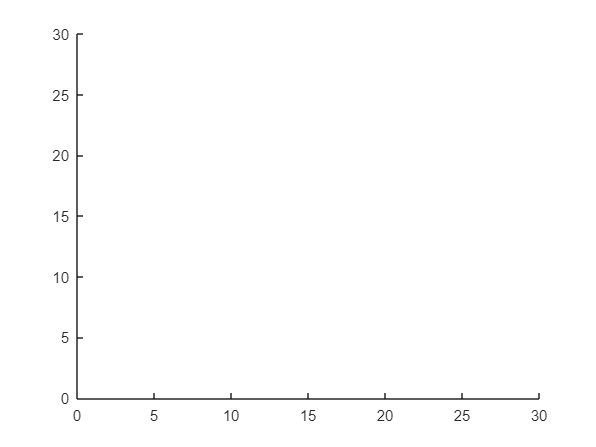

hold off
Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);
%mark the starting location
InitialPosition = [0 0 0];
InitialOrientation = [0 0 0];
InitialWPS = [InitialPosition; 0 0 -10];
addMesh(Scenario,"cylinder",{[InitialPosition(2) InitialPosition(1) 1] [0 .01]},[0 1 1]);  

%create a UAV model in the scenario
platUAV = uavPlatform("UAV",Scenario, ...
                    "ReferenceFrame","ENU", ...
                    "InitialPosition",InitialPosition, ...
                    "InitialOrientation",eul2quat(InitialOrientation));

%add the drone mesh over the model (style,size,color,orientation)
updateMesh(platUAV,"quadrotor",{1},[1 0 1],eul2tform([0 0 pi]));
xlim([0 30]);  
ylim([0 30]);

### Run the simulation and extract data

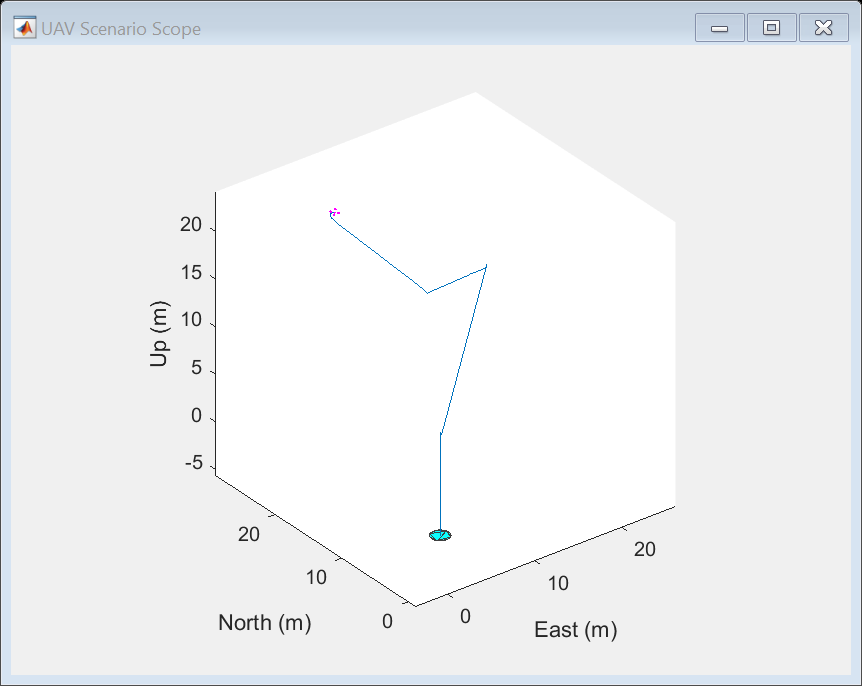

out = sim("HelloDrone.slx");


%extract the drones trajectory
points = squeeze(out.trajectoryPoints(1,:,:))';

%extract the waypoints
    Waypoints = squeeze(out.waypoints)';
    Waypoints = unique(Waypoints, 'rows','stable');

### Plot the waypoints & trajectory

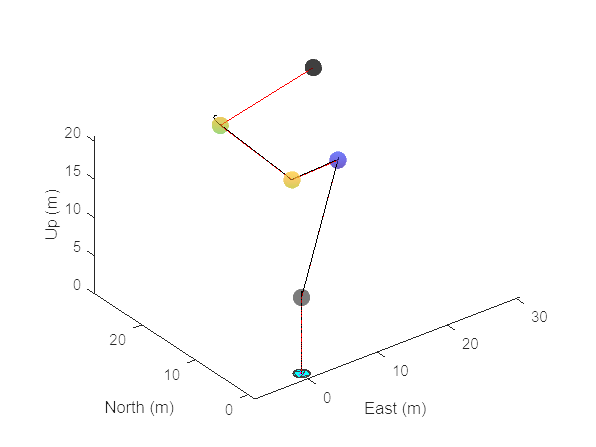

clf;
hold on;
[X,Y,Z] = sphere;
%plot the first waypoint in cyan
surf(X+Waypoints(1,2), Y+Waypoints(1,1), Z-Waypoints(1,3),'FaceAlpha',0.3,'EdgeColor','none','FaceColor','black')
for i = 2:size(Waypoints,1)-1
    %To view the waypoints DURING the flight sim, uncomment
    %addMesh(Scenario,"cylinder",{[Waypoints(i,2) Waypoints(i,1) 1] [0 0.1]},[0 .8 .3]);
    surf(X+Waypoints(i,2), Y+Waypoints(i,1), Z-Waypoints(i,3),'FaceAlpha',0.5,'EdgeColor','none')
end
%plot the final waypoint in black
surf(X+Waypoints(end,2), Y+Waypoints(end,1), Z-Waypoints(end,3),'FaceAlpha',0.5,'EdgeColor','none','FaceColor','black')

%plot the straight line path between points
plot3([InitialPosition(1,2); Waypoints(:,2)],[InitialPosition(1,2); Waypoints(:,1)],[-InitialPosition(1,3); -Waypoints(:,3)],"-r");

%plot the trajectory (BLACK)
plot3(points(:,2),points(:,1),-points(:,3),"-k");

show3D(Scenario);

### Simulation Report

disp("Simulation Report ---")

Simulation Report ---


str = 'Total Time: '; value = out.tout(end); fprintf('%s %.3f\n', str, value);

Total Time:  50.000



slDist = 0;
for i = 1:size(Waypoints)-1
        slDist = slDist + sqrt(sum((Waypoints(i+1, :) - Waypoints(i, :)).^2));
end
str = 'Straight Line Distance: '; value = slDist; fprintf('%s %.3f\n', str, value);

Straight Line Distance:  85.966



ptts = out.trajectoryPoints(:,:,:);
dist = 0;
for i = 1:size(ptts(:,:,:),3)-1
    dist = dist + sqrt(sum((ptts(:,:,i+1, :) - ptts(:,:,i, :)).^2));
end
str = 'Total Distance: '; value = dist; fprintf('%s %.3f\n', str, value);

Total Distance:  87.247



str = 'Number of waypoints: '; value = size(Waypoints); fprintf('%s %d\n', str, value);

Number of waypoints:  5
□ 